# GReS - Unsaturated Flow in a Porous media - Richard's model

## Introduction

This is a tutorial describing how to use the unsaturated flow in a porous media using Richards modulo currently available in GReS.

cd(fullfile(gres_root,'Tutorial','sedimentation'))
sedimentation_root = fullfile(gres_root,'Tests','Sedimentation','LinearSedimentation2D');

## Governing equations

Mass conservation of slightly compressible unsaturated fluid is given by


$$\sigma(S) \frac{\partial p}{\partial t} + \nabla \cdot \bigg( \lambda(S) \mathbf{K} \nabla ( p + \gamma z)\bigg)= q,$$
   

where:

- $\sigma$ is the store coefficient;

- $\lambda$ is the fluid mobility;

- $\mathbf{K}$ is the permeability tensor;

- $ \gamma$ is the specific weight of the fluid;

- $q$ is the external volumetric flux;

- $p$ is the pressure field;

- $z$ is the height;

- $S$ is the saturation.

The following boundary conditions can be prescribed


$$\begin{cases}
    p(\mathbf{x},t) = p_D(\mathbf{x},t) 
    & \text{on } \,  \Gamma_p:\ \text{prescribed pressure} \\[6pt]

    \mathbf{q}(\mathbf{x},t) \cdot \mathbf{n}(\mathbf{x}) = q_N(\mathbf{x},t) 
    & \text{on } \, \Gamma_q:\ \text{prescribed flux}
\end{cases}
$$


In this model, the primary variable is the pressure field and the variables $\sigma$ and $\lambda$ are dependent on the saturation level. The store coefficient coded in GReS is expressed as


$$\sigma(S) = S\bigg(\alpha+\beta\phi\bigg) + \phi\frac{dS}{dp}$$


where: 

- $\alpha$ - rock compressibility;

- $\beta$ - fluid compressibility;

- $\phi$ - porosity;

and the fluid mobility is given by


$$\lambda(S) = \frac{k_{r}(S)}{\mu}$$


- $k_{r}(S)$ is relative permeability of the fluid;

- $\mu$ is the dynamic viscosity of the fluid.

## Problem setting

This numerical experiment reproduces a modified version of the study described by Varella, 2018. It simulates the one-dimensional, incompressible version of Richards' equation. The domain is a 100 cm-long column of initially dry soil. A higher pressure head is imposed at the top boundary, which causes a water infiltration front to develop and move downward over time.

## Preprocessor Phase - Model setup

### Materials

To define the materials in the simulation, you create a new instance of the `Materials` class. This object takes a file containing the material values and a `Model` object as input.

mat = Materials(fullfile(sedimentation_root,'Input','materials.xml'));

**The user is responsible for the dimensional consistency of all physical quantities involved in the model.**

we need an input file file containing the list of the materials

**.xml File Format** -> materials.xml

The **fluid** is always defined for the **entire domain**, thus requiring only **one block** with its properties. **If more the one block are specified for a fluid material, GReS will throw an error.**  This block `holds` the specific weight of the fluid (here assumed to be 0 to neglect gravitational effects), the fluid compressibility, and the dynamic viscosity.

**Fluid Block** 

**Solid Block** 

To solve the physics of this simulation, you must define `the`  `<Curves> `block inside the `<PorousRock>`, which stores information on the relative permeability and capillary curves for unsaturated flow models.  

mat.solid{1}

ans = struct with fields:
              name: "peat"
    specificWeight: 0
          ConstLaw: [1×1 SedimentMaterial]


In GReS, the variables $S$ and $k_{r}$ are a function of pressure and can be defined in three in three different ways: through tabulated data, via the van Genuchten model Genuchten, 1980, Genuchten, 1985, MRST, 2019 or by choosing some standard preset values from a list of rock types. In these cases, the saturation is described in terms as effective saturation, following


$$S_{e} = \frac{S-S_{r}}{S_{s}-S_{r}}$$


with:

- $S$ is the saturation;

- $S_{e}$ is the effective saturation;

- $S_{r}$ is the residual saturation;

- $S_{s}$ is the maximum saturation for the fluid.

#### Tabular Data format

In this case, the variables $S_{e}$ and $k_{r}$ are store in a table that contains the information about the variable and its correspondent pressure (see fig:Tabular Curves). 

*Tabular Curves: Example of tabular curves for the effective saturation and the relative permeability.*

When you call the VanGenuchten in the "Curves block", you must provide the file path as follows:

The type "`tabular"` block defines the saturation and relative permeability properties discretely, representing them as a point cloud that associates a pressure level with the corresponding property. Both curves are provided in a separate data file. We recommend that this file use a large number of points (more than 500) to ensure the stability and convergence of the non linear solver. Although the points do not need to be uniformly spaced, it is essential to have a higher density in the nonlinear regions of the curves, where the property's behavior changes more rapidly. Furthermore, to satisfy the requirement that both curves be C2 continuity, the derivative at both ends of the domain is assumed to be zero.

#### Van Genuchten model

The relationship between capillary pressure and water saturation is given by


$$S_{e} = \bigg(1+(\hat\beta p)^{n}\bigg)^{-m}$$


- $\hat\beta$ is related to the average size of pores

- $n$ and $m$ are experimental parameters.

The relative permeability be given by the van Genuchten–Mualem model,


$$k_{r} = S_{e}^{k}\bigg[1-\bigg(1 - S_{e}^{1/m}\bigg)^{m}\bigg]^{2},    \quad m=1-1/n$$


where $k$ is a connectivity factor, usually 0.5. Or by the van Genuchten-Burdine model,


$$k_{r} = S_{e}^{2}\bigg[1-\bigg(1 - S_{e}^{1/m}\bigg)^{m}\bigg],    \quad m=1-2/n$$


When the type "mualem" is used, it signals that you are employing the van Genuchten–Mualem model, followed by the parameters $n$, $\hat \beta$ and *k* in that order. In contrast, if the type "b`urdine"` is used, it indicates the use of the van Genuchten–Burdine model, which does not require the k parameter. Here, you only provide *n* and $\hat \beta$. For both models, the *n* and *k* parameters are adimensional, while the $\hat \beta$ parameter's value is dependent on the units used throughout your simulation.

#### Preset format

In this case, the saturation and relative permeability are described by the van Genuchten–Mualem model for some standard soil types, with its parameters stored internally. The available rock types are listed in the following table:

You can define parameters necessary simply specifying the rock type from the table, in this case for example is `"Sand"`.

### Domain

To define the domain, you must first specify a grid. This is covered in detail in [Tutorial - Grid](matlab:open('../mesh/mesh.mlx')), so here we will only provide the necessary commands.

## Processor Phase - Solution

### Boundary condition

The boundary conditions are defined as 

The boundary conditions are defined in the XML file, and the description of this file will be addressed in a dedicated tutorial on this topic. However, for immediate reference, we recommend utilizing [Tutorial - Terzaghi.](matlab:open('../terzaghiPoroelasticity/terzaghi.mlx'))

### Discretizer

We instantiate the Discretizer class to create a domain object. This class acts as a wrapper for all previously defined objects, storing a database of the model's physical solvers in its solver property. It also includes a State property, which is an object that holds the primary variables and derived quantities of the model for a specific point in time.

domain = Discretizer('Materials',mat);

For more details on this process, please refer to the [Tutorial - Terzaghi.](matlab:open('../terzaghiPoroelasticity/terzaghi.mlx'))

### Setting the physics

This step establishes the physical laws and principles that govern the behavior of the simulation. The active physical models are defined by the command

domain.addPhysicsSolvers(fullfile(sedimentation_root,'Input','solver.xml'));

For the Richards problem, you need to pass "VariablySaturatedFlow".

**The "VariablySaturatedFlow****" ****module is implemented only for the finite volume method formulation.**

### Initial condition

If your simulation requires a non-zero starting state, you need to directly access and modify the `State` object before running the simulation. 

In this experiment, the initial condition for the domain is a constant pressure distribution.

## Simulation loop

We specify the simulation parameters by creating a `SimulationParameters` object. 

This is created by the command

simParam = SimulationParameters('Start',0.,'End',1.0e3,...
      'DtInit',1e-0,'DtMin',1e-2,'DtMax',1e-0,'MaxNLIteration',30);

To finalize the domain definition, you'll control the output details of the simulation by creating an instance of the `OutState` class.

printUtils = OutState('outputFile','Outputs/Results','printTimes',0:25:1000);

We are now ready to set up the solver:

solver = EvolvingGrid('simulationparameters',simParam,...
                           'domains',domain,...
                           'output',printUtils, ...
                           'growprint',0);

The actual simulation—namely, the time-stepping loop—is executed by the simulationLoop`()` method, as described in [Tutorial - Terzaghi](matlab:open('../terzaghiPoroelasticity/terzaghi.mlx')) for reference. 

solver.simulationLoop();


TSTEP 1   ---  TIME 1.000000  --- DT = 1.000000e+00
-----------------------------------------------------------
Iter     ||rhs||     ||rhs||/||rhs_0||
0     4.611861e-04     1.000000e+00
1     1.170736e-06     2.538532e-03
2     1.946913e-09     4.221534e-06
3     3.237695e-12     7.020365e-09

TSTEP 2   ---  TIME 2.000000  --- DT = 1.000000e+00
-----------------------------------------------------------
Iter     ||rhs||     ||rhs||/||rhs_0||
0     5.736895e-04     1.000000e+00
1     8.371154e-07     1.459178e-03
2     9.395502e-10     1.637733e-06
3     1.629234e-12     2.839923e-09

TSTEP 3   ---  TIME 3.000000  --- DT = 1.000000e+00
-----------------------------------------------------------
Iter     ||rhs||     ||rhs||/||rhs_0||
0     3.506872e-04     1.000000e+00
1     9.513284e-07     2.712755e-03
2     1.129047e-09     3.219527e-06
3     1.953125e-12     5.569424e-09

TSTEP 4   ---  TIME 4.000000  --- DT = 1.000000e+00
-----------------------------------------------------------

## Posprocessor Phase - Evaluating the Results 

A .pvd file will be created in the folder specified by the "outFolder" option in your OutState object. You can then visualize the solution using dedicated software such as [ParaView](https://www.paraview.org/) or [VisIt](https://visit-dav.github.io/visit-website/index.html).

## 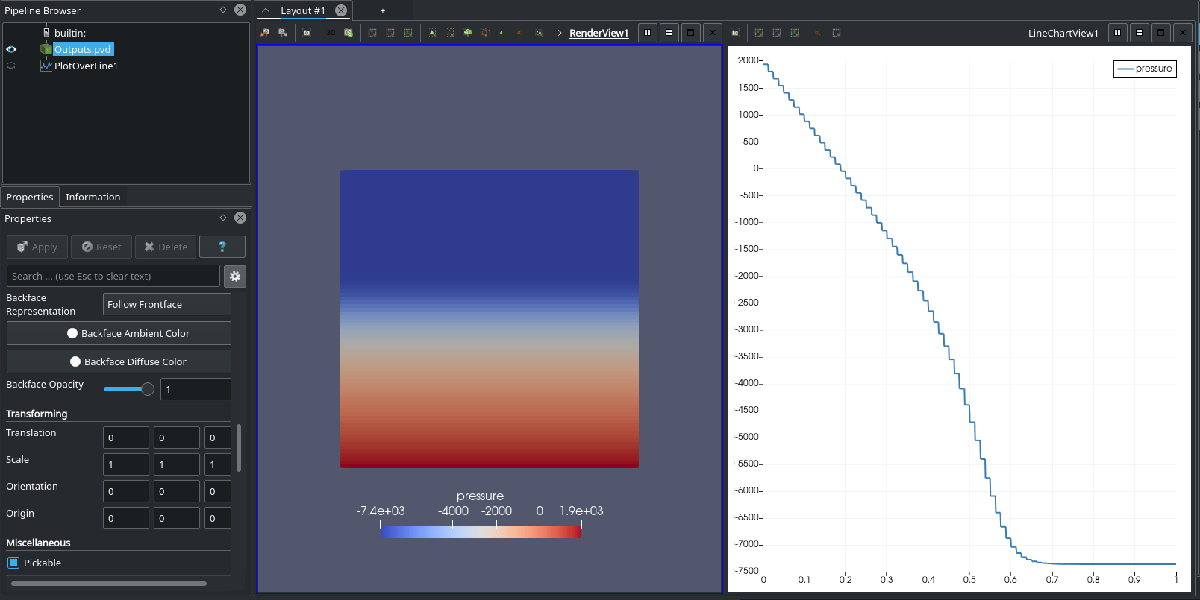

Figure: Pressure field and pressure path in the middle of the domain in the z axis.

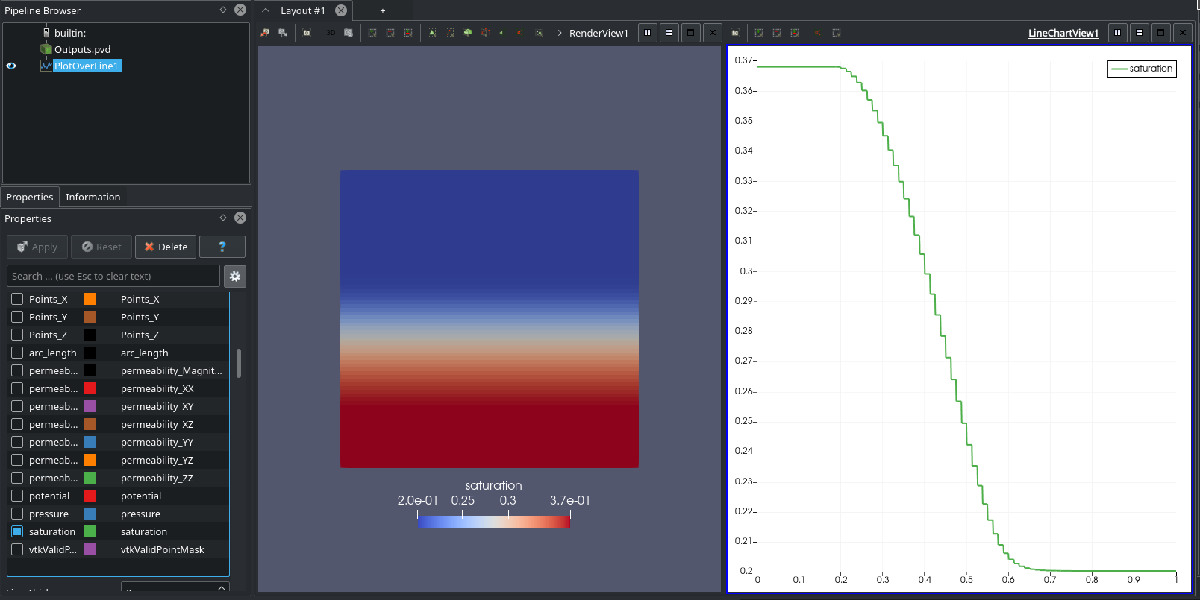

Figure: Saturation field and saturation path in the middle of the domain in the z axis.

## References

*M. Th. van Genuchten. A Closed-form Equation for Predicting the Hydraulic Conductivity of Unsaturated Soils. In: Soil Science Society of America Journal 44.5 (1980), pp. 892–898. doi: *[*https://doi.org/10.2136/sssaj1980.03615995004400050002x*](https://doi.org/10.2136/sssaj1980.03615995004400050002x)

*Martinus Van Genuchten and D.R. Nielsen. On Describing and Predicting the Hydraulic Properties of Unsaturated Soils. In: Annales Geophysicae 3 (Jan. 1985), pp. 615–628.*

*Knut-Andreas Lie. An Introduction to Reservoir Simulation Using MATLAB/GNU Octave: User Guide for the MATLAB Reservoir Simulation Toolbox (MRST). Cambridge University Press, 2019*

*Varela, Jhabriel. Implementation of an MPFA/MPSA-FV solver for the unsaturated flow in deformable porous media. 2018.*